clc                     % clear command window
clear                   % clear MATLAB workspace
clf

[robotArduino]= SETUPARDUINO('COM3') 

robotArduino =   arduino with properties:

                  Port: 'COM3'
                 Board: 'Nano33BLE'
         AvailablePins: {'D0-D13', 'A0-A7'}
  AvailableDigitalPins: {'D0-D13', 'A0-A7'}
      AvailablePWMPins: {'D0-D13'}
   AvailableAnalogPins: {'A0-A3', 'A6-A7'}
    AvailableI2CBusIDs: [0, 1]
AvailableSerialPortIDs: [1]
             Libraries: {'I2C', 'Servo'}
Show all properties


steerServo = servo(robotArduino, 'D5', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
driveServo = servo(robotArduino, 'D3', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);
panServo = servo(robotArduino, 'D6', 'MinPulseDuration', 1466*10^-6, ...
      'MaxPulseDuration', 1536*10^-6);

writePosition(steerServo, 0.5);      % always start servo-command at 0.5
writePosition(driveServo, 0.3);      % always start servo-command at 0.5
writePosition(panServo, 0.5);        % always start servo-command at 0.5
pause(3.0);                          % wait for Arduino to send stable pwm
warning ('actuators live');

% calibrate to 0.1 - 0.3 - 0.9
writePosition(driveServo, 0.3);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

joy=vrjoystick(1); 
while true
    one = axis(joy, 1)
    two = axis(joy, 2)
    three = axis(joy, 3)
    writePosition(steerServo, -one*0.16 + 0.54)
    writePosition(driveServo, -two*0.02 + 0.35)
    writePosition(panServo, -three*0.5 + 0.5)
    
    pause(0.01)


end

clear lid
lid = LIDAR('COM6')

lid =   LIDAR with properties:

        lidar: [1×1 serial]
     pol_data: []
    cart_data: []


lidar_data = lid.scan(5000);

lid.close()

gps = NEO_M8U_USB('COM4')


gps_data = gps.getBasic();

clear gps 

lidar_data = lid.scan(10000);
left = lidar_data(:, lidar_data(2,:) > 0 & 0 < lidar_data(1,:) < 500);
plot(left(1,:), left(2,:), '*')
right = lidar_data(:, lidar_data(2,:) < 0 & 0 < lidar_data(1,:) < 500);
plot(right(1,:), right(2,:), '*')
    
lefts = sort(abs(sqrt(left(1,:).^2 + left(2,:).^2)));
rights = sort(abs(sqrt(right(1,:).^2 + right(2,:).^2)));

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');
hold off;


plot(lidar_data(1,:), lidar_data(2,:), '*')

save('4-27-lg-01', "lidar_data")

Wall aviod basic

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.38)
    left = lidar_data(:, lidar_data(2,:) > 10 & 100 < lidar_data(1,:) < 8000);
    
    right = lidar_data(:, lidar_data(2,:) < -10 & 100 < lidar_data(1,:) < 8000);
    

    hold on
    clf
    %plot x coor, y coord, and object identity
    plot(lidar_data(2,:), lidar_data(1,:), '*')

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    lefts = sort(sqrt(abs(left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(right(1,:).^2) + abs(right(2,:).^2)));

    if isempty(rights)
        rights = [20000; 20000];
    elseif isempty(lefts)
        lefts = [20000; 20000];
    end
    
    if min(lefts) < 6000 & (min(lefts) < min(rights))
        writePosition(steerServo, 0.3*0.16 + 0.52);
        title('left')
    elseif min(rights) < 6000 & (min(rights) < min(lefts))
        writePosition(steerServo, -0.3*0.16 + 0.52);
        title('right')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end
    pause(0.6)
end

Wall aviod with gradient match

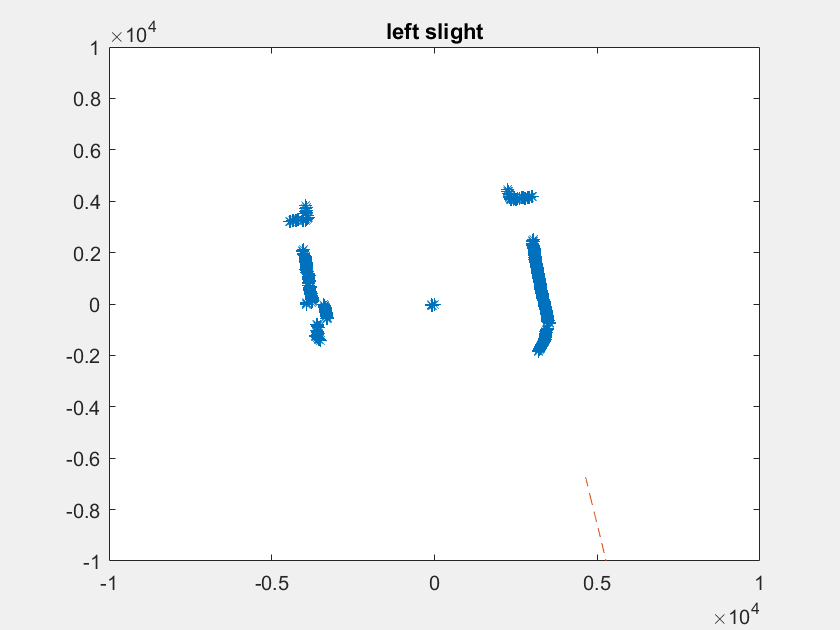

   3.4094e+03



slope = 8.3865

   3.5228e+03



slope = 2.1277

   4.0612e+03



slope = -3.0125

   3.9435e+03



slope = -2.7406

   3.4368e+03



slope = -0.6037

   3.8082e+03



slope = -2.8881

   3.6603e+03



slope = -3.5926

   3.3600e+03



slope = 0.8173

   3.1993e+03



slope = 2.1636

   2.8618e+03



slope = -2.8879

   2.7687e+03



slope = -2.5487

   2.8358e+03



slope = 1.0161

   2.9460e+03



slope = 3.6462

   3.0660e+03



slope = 6.6137

   3.3667e+03



slope = 7.7334

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.375)
    left = lidar_data(:, lidar_data(1,:) < -300 & 300 < lidar_data(2,:) < 4000);
    
    right = lidar_data(:, lidar_data(1,:) > 300 & 300 < lidar_data(2,:) < 4000);
    
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    disp(min(rights))

    fit = polyfit(right(1,:), right(2,:),1);
    slope = fit(1)
    yfit = fit(1)*rights(1,:)+fit(2);

    if isempty(rights)
        rights = [20000; 20000];
        slope = 0;
    elseif isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %plot x coor, y coord, and object identity
    plot(lidar_data(1,:), lidar_data(2,:), '*')
    hold on
    if ~(isempty(rights)) & ~(isempty(yfit))
        plot(rights(1,:), yfit, '--')
    end

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    if min(lefts) < 3000 & (min(lefts) < min(rights))
        writePosition(steerServo, -0.4*0.16 + 0.52);
        title('right')
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        writePosition(steerServo, 0.4*0.16 + 0.52);
        title('left')
    elseif slope > 0
        writePosition(steerServo, -0.2*0.16 + 0.52);
        title('right slight')
    elseif slope < 0
        writePosition(steerServo, 0.2*0.16 + 0.52);
        title('left slight')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end

    pause(0.5)
end

RANSAC fit

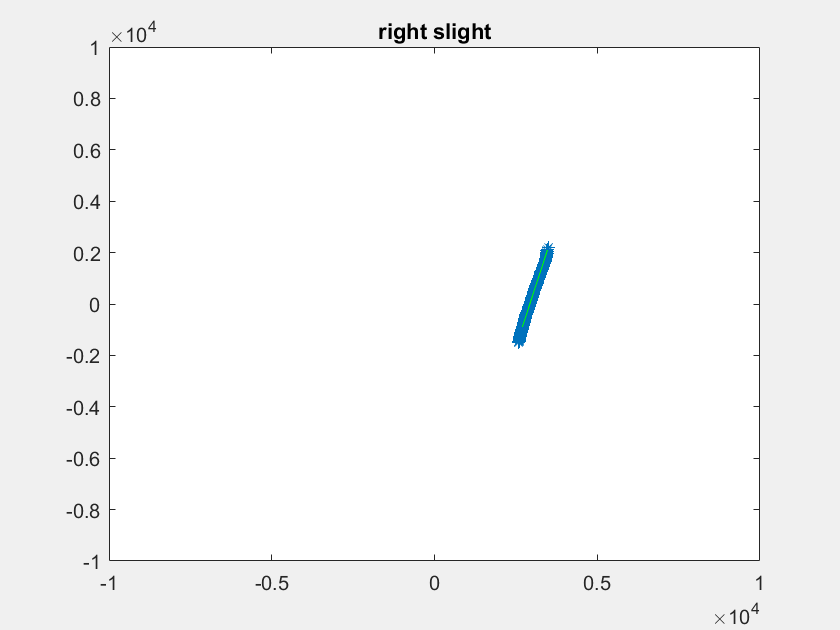

   2.7951e+03



rpoints = 	1.0e+03 *

    2.3261   -1.3430
    2.3231   -1.3223
    2.3154   -1.2992
    2.3155   -1.2806
    2.3189   -1.2639
    2.3178   -1.2449
    2.3228   -1.2293
    2.3037   -1.2011
    2.3066   -1.1846
    2.3120   -1.1695


slope = 2.5157

   3.7517e+03



rpoints = 	1.0e+03 *

    2.4560   -1.4180
    2.5003   -1.4232
    2.5099   -1.4083
    2.5176   -1.3923
    2.5261   -1.3769
    2.5337   -1.3608
    2.5305   -1.3392
    2.5333   -1.3208
    2.5467   -1.3080
    2.5556   -1.2928


slope = 5.9598

   4.0852e+03



rpoints = 	1.0e+03 *

    2.7297   -1.5760
    2.7393   -1.5592
    2.7489   -1.5424
    2.7583   -1.5254
    2.7729   -1.5113
    2.7821   -1.4943
    2.7921   -1.4776
    2.8011   -1.4605
    2.8101   -1.4432
    2.8189   -1.4259


slope = -0.2256

   3.7582e+03



rpoints = 	1.0e+03 *

    2.4716   -1.4270
    2.4804   -1.4118
    2.4829   -1.3931
    2.4809   -1.3720
    2.4805   -1.3520
    2.4887   -1.3367
    2.4943   -1.3200
    2.5023   -1.3047
    2.4978   -1.2829
    2.5057   -1.2675


slope = 2.3387

   4.0129e+03



rpoints = 	1.0e+03 *

    2.7704   -1.5995
    2.7793   -1.5820
    2.7890   -1.5649
    2.7714   -1.5327
    2.7781   -1.5142
    2.7874   -1.4971
    2.7965   -1.4800
    2.8056   -1.4628
    2.8145   -1.4455
    2.8305   -1.4318


slope = -16.3485

   3.8072e+03



rpoints = 	1.0e+03 *

    2.4924   -1.4390
    2.5012   -1.4237
    2.5230   -1.4156
    2.5343   -1.4015
    2.5428   -1.3860
    2.5513   -1.3703
    2.5597   -1.3546
    2.5679   -1.3389
    2.5788   -1.3244
    2.5886   -1.3095


slope = 1.3423

   3.7907e+03



rpoints = 	1.0e+03 *

    2.7799   -1.6050
    2.7915   -1.5889
    2.8090   -1.5761
    2.8292   -1.5646
    2.8545   -1.5558
    2.8676   -1.5402
    2.8778   -1.5230
    2.8871   -1.5053
    2.9115   -1.4953
    2.9126   -1.4733


slope = -8.3100

   3.4717e+03



rpoints = 	1.0e+03 *

    2.7323   -1.5775
    2.7324   -1.5552
    2.7410   -1.5379
    2.7495   -1.5206
    2.7588   -1.5037
    2.7645   -1.4848
    2.7735   -1.4678
    2.7825   -1.4507
    2.7905   -1.4332
    2.8001   -1.4165


slope = -7.0119

   3.2792e+03



rpoints = 	1.0e+03 *

    2.7825   -1.6065
    2.7924   -1.5894
    2.7951   -1.5683
    2.8020   -1.5496
    2.7878   -1.5195
    2.7909   -1.4990
    2.7789   -1.4706
    2.7825   -1.4507
    2.7896   -1.4327
    2.7948   -1.4138


slope = -9.4123

   3.1578e+03



rpoints = 	1.0e+03 *

    2.7072   -1.5630
    2.7150   -1.5454
    2.7210   -1.5267
    2.7285   -1.5090
    2.7316   -1.4888
    2.7151   -1.4583
    2.7241   -1.4416
    2.7320   -1.4244
    2.7264   -1.4003
    2.7323   -1.3822


slope = 10.4424

   3.0590e+03



rpoints = 	1.0e+03 *

    2.7548   -1.5905
    2.7585   -1.5701
    2.7524   -1.5443
    2.7513   -1.5216
    2.7527   -1.5003
    2.7566   -1.4806
    2.7479   -1.4542
    2.7373   -1.4272
    2.7229   -1.3985
    2.7296   -1.3808


slope = 5.5960

   2.9342e+03



rpoints = 	1.0e+03 *

    2.8111   -1.6230
    2.8150   -1.6022
    2.8021   -1.5722
    2.8047   -1.5511
    2.8133   -1.5334
    2.8191   -1.5142
    2.8071   -1.4856
    2.8109   -1.4655
    2.8145   -1.4455
    2.7912   -1.4119


slope = -6.7301

   2.9682e+03



rpoints = 	1.0e+03 *

    2.7314   -1.5770
    2.7237   -1.5503
    2.7262   -1.5296
    2.7128   -1.5003
    2.7158   -1.4802
    2.7187   -1.4602
    2.7223   -1.4407
    2.7213   -1.4188
    2.6891   -1.3811
    2.6948   -1.3632


slope = -7.8901

   3.1937e+03



rpoints = 	1.0e+03 *

    2.1278   -1.2285
    2.1327   -1.2139
    2.1210   -1.1900
    2.1247   -1.1751
    2.1143   -1.1524
    2.1134   -1.1351
    2.1151   -1.1193
    2.1210   -1.1059
    2.1260   -1.0919
    2.1327   -1.0788


slope = 2.7100

   3.6826e+03



rpoints = 	1.0e+03 *

    2.6293   -1.5180
    2.6290   -1.4964
    2.6294   -1.4753
    2.6296   -1.4543
    2.6315   -1.4343
    2.6253   -1.4101
    2.6321   -1.3930
    2.6309   -1.3717
    2.6330   -1.3523
    2.6217   -1.3262


slope = 2.2125

   3.7369e+03



rpoints = 	1.0e+03 *

    2.6899   -1.5530
    2.6881   -1.5300
    2.6939   -1.5115
    2.6918   -1.4887
    2.6877   -1.4649
    2.6861   -1.4427
    2.6931   -1.4252
    2.6938   -1.4045
    2.6802   -1.3765
    2.6841   -1.3578


slope = 2.8208

   3.8528e+03



rpoints = 	1.0e+03 *

    2.7462   -1.5855
    2.7385   -1.5587
    2.7445   -1.5399
    2.7530   -1.5225
    2.7518   -1.4999
    2.7275   -1.4649
    2.7347   -1.4472
    2.7364   -1.4267
    2.7398   -1.4071
    2.7314   -1.3817


slope = 3.4955

   4.0144e+03



rpoints = 	1.0e+03 *

    2.7886   -1.6100
    2.7897   -1.5879
    2.7820   -1.5609
    2.7819   -1.5385
    2.7825   -1.5166
    2.7733   -1.4895
    2.7718   -1.4669
    2.7657   -1.4420
    2.7629   -1.4190
    2.7457   -1.3889


slope = 3.1927

   4.1846e+03



rpoints = 	1.0e+03 *

    2.8484   -1.6445
    2.8445   -1.6191
    2.8308   -1.5883
    2.8152   -1.5569
    2.8071   -1.5300
    2.8068   -1.5075
    2.7930   -1.4781
    2.7763   -1.4475
    2.7851   -1.4304
    2.7939   -1.4133


slope = -2.0099

   3.8919e+03



rpoints = 	1.0e+03 *

    2.7087   -1.5198
    2.7272   -1.4865
    2.7363   -1.4697
    2.6869   -1.4220
    2.6956   -1.4054
    2.7611   -1.4181
    2.7546   -1.3934
    2.7631   -1.3765
    2.7715   -1.3595
    2.7609   -1.3333


slope = -0.0115

   3.8029e+03



rpoints = 	1.0e+03 *

    2.6067   -1.5050
    2.5942   -1.4766
    2.5788   -1.4469
    2.5736   -1.4233
    2.5823   -1.4075
    2.5892   -1.3907
    2.5906   -1.3710
    2.5910   -1.3509
    2.5930   -1.3318
    2.5913   -1.3108


slope = 2.9499

   3.4760e+03



rpoints = 	1.0e+03 *

    2.8232   -1.6300
    2.8315   -1.6116
    2.8413   -1.5942
    2.8362   -1.5685
    2.8370   -1.5463
    2.8350   -1.5227
    2.8504   -1.5085
    2.8481   -1.4850
    2.8572   -1.4674
    2.8608   -1.4472


slope = 0.0073

   3.3346e+03



rpoints = 	1.0e+03 *

    2.8478   -1.5071
    2.8827   -1.5030
    2.9088   -1.4939
    2.9188   -1.4765
    2.9368   -1.4630
    2.9511   -1.4476
    2.9617   -1.4303
    2.9704   -1.4121
    3.0053   -1.4061
    3.0139   -1.3876


slope = 0.1403

   2.7486e+03



rpoints = 	1.0e+03 *

    2.8386   -1.3494
    2.8523   -1.3345
    2.8604   -1.3169
    2.8703   -1.3002
    2.8782   -1.2825
    2.8997   -1.2708
    2.9075   -1.2530
    2.9179   -1.2363
    2.9254   -1.2183
    2.9514   -1.2079


slope = 0.2628

   2.1508e+03



rpoints = 	1.0e+03 *

    2.5158   -1.4525
    2.5429   -1.4474
    2.5649   -1.4391
    2.5736   -1.4233
    2.5823   -1.4075
    2.5848   -1.3883
    2.5791   -1.3649
    2.5608   -1.3352
    2.5681   -1.3190
    2.5592   -1.2946


slope = 0.2763

   1.6824e+03



rpoints = 	1.0e+03 *

    2.3166   -1.3375
    2.3248   -1.3232
    2.3180   -1.3006
    2.3234   -1.2849
    2.3180   -1.2634
    2.3117   -1.2416
    2.3166   -1.2260
    2.3090   -1.2039
    2.3128   -1.1878
    2.3129   -1.1700


slope = 0.1534

   1.3388e+03



rpoints = 	1.0e+03 *

    1.2055   -0.6960
    1.2080   -0.6876
    1.2052   -0.6762
    1.2068   -0.6674
    1.2108   -0.6600
    1.2131   -0.6516
    1.2144   -0.6427
    1.2148   -0.6334
    1.2187   -0.6259
    1.2198   -0.6170


slope = 0.0182

   1.2406e+03



rpoints = 	1.0e+03 *

    1.1847   -0.6840
    1.1819   -0.6728
    1.1861   -0.6655
    1.1884   -0.6572
    1.1924   -0.6499
    1.1928   -0.6407
    1.1994   -0.6347
    1.1980   -0.6246
    1.2053   -0.6190
    1.2091   -0.6116


slope = 3.8629

   1.3057e+03



rpoints = 	1.0e+03 *

    1.2401   -0.7160
    1.2445   -0.7084
    1.2497   -0.7012
    1.2540   -0.6935
    1.2582   -0.6858
    1.2536   -0.6733
    1.2577   -0.6656
    1.2618   -0.6579
    1.2640   -0.6492
    1.2662   -0.6405


slope = 2.4815

   1.4702e+03



rpoints = 	1.0e+03 *

    0.9639   -0.5565
    0.9682   -0.5511
    0.9663   -0.5422
    0.9696   -0.5362
    0.9729   -0.5303
    0.9744   -0.5233
    0.9775   -0.5173
    0.9798   -0.5109
    0.9794   -0.5030
    0.9842   -0.4979


slope = 2.1520

   2.3706e+03



rpoints = 	1.0e+03 *

    1.5519   -0.8960
    1.5574   -0.8865
    1.5602   -0.8754
    1.5612   -0.8634
    1.5664   -0.8538
    1.5681   -0.8422
    1.5733   -0.8326
    1.5766   -0.8220
    1.5816   -0.8123
    1.5857   -0.8021


slope = 1.9463

   2.7846e+03



rpoints = 	1.0e+03 *

    1.8845   -1.0880
    1.8807   -1.0705
    1.8776   -1.0535
    1.8701   -1.0342
    1.8738   -1.0213
    1.8765   -1.0079
    1.8738   -0.9916
    1.8798   -0.9801
    1.8858   -0.9685
    1.8917   -0.9569


slope = 1.9683

   3.0889e+03



rpoints = 	1.0e+03 *

    2.0222   -1.1675
    2.0293   -1.1551
    2.0381   -1.1436
    2.0477   -1.1325
    2.0546   -1.1199
    2.0650   -1.1091
    2.0718   -1.0964
    2.0785   -1.0837
    2.0753   -1.0659
    2.0916   -1.0581


slope = 2.0139

   3.3720e+03



rpoints = 	1.0e+03 *

    2.2075   -1.2745
    2.2222   -1.2649
    2.2317   -1.2522
    2.2332   -1.2351
    2.2408   -1.2213
    2.2482   -1.2075
    2.2547   -1.1932
    2.2620   -1.1794
    2.2657   -1.1636
    2.2728   -1.1497


slope = 1.0464

   3.5638e+03



rpoints = 	1.0e+03 *

    2.3331   -1.3470
    2.3396   -1.3317
    2.3477   -1.3173
    2.3557   -1.3028
    2.3628   -1.2878
    2.3680   -1.2719
    2.3758   -1.2573
    2.3835   -1.2427
    2.3902   -1.2276
    2.3968   -1.2124


slope = 1.1426

   3.7371e+03



rpoints = 	1.0e+03 *

    2.4465   -1.4125
    2.4517   -1.3955
    2.4602   -1.3804
    2.4660   -1.3638
    2.4743   -1.3486
    2.4729   -1.3282
    2.4810   -1.3130
    2.4801   -1.2931
    2.4880   -1.2778
    2.5030   -1.2661


slope = 1.2549

   3.9210e+03



rpoints = 	1.0e+03 *

    2.5669   -1.4820
    2.5760   -1.4662
    2.5849   -1.4504
    2.5841   -1.4291
    2.5929   -1.4132
    2.6015   -1.3973
    2.6100   -1.3813
    2.6061   -1.3587
    2.6117   -1.3413
    2.6199   -1.3253


slope = 1.5381

   4.0771e+03



rpoints = 	1.0e+03 *

    2.6691   -1.5410
    2.6915   -1.5320
    2.7009   -1.5154
    2.6970   -1.4916
    2.7140   -1.4793
    2.7134   -1.4574
    2.7205   -1.4397
    2.7293   -1.4230
    2.7380   -1.4062
    2.7466   -1.3894


slope = 1.7601

   4.1935e+03



rpoints = 	1.0e+03 *

    2.7453   -1.5850
    2.7550   -1.5681
    2.7646   -1.5512
    2.7740   -1.5341
    2.7922   -1.5219
    2.8015   -1.5047
    2.8107   -1.4875
    2.8162   -1.4683
    2.8252   -1.4510
    2.8260   -1.4295


slope = 2.1900

   4.2628e+03



rpoints = 	1.0e+03 *

    2.8230   -1.4940
    2.8348   -1.4780
    2.8625   -1.4702
    2.8795   -1.4566
    2.8902   -1.4398
    2.9044   -1.4247
    2.9185   -1.4094
    2.9280   -1.3919
    2.9365   -1.3739
    2.9449   -1.3558


slope = 2.6072

   4.4184e+03



rpoints = 	1.0e+03 *

    2.8925   -1.6700
    2.9027   -1.6522
    2.9146   -1.6353
    2.9272   -1.6188
    2.9546   -1.6104
    2.9645   -1.5922
    2.9742   -1.5740
    2.9838   -1.5557
    2.9933   -1.5373
    3.0000   -1.5176


slope = 3.5105

   4.2398e+03



rpoints = 	1.0e+03 *

    2.7756   -1.6025
    2.7993   -1.5933
    2.8090   -1.5761
    2.8265   -1.5632
    2.8414   -1.5487
    2.8508   -1.5312
    2.8619   -1.5146
    2.8836   -1.5035
    2.9043   -1.4917
    2.9188   -1.4765


slope = 4.0730

   4.3120e+03



rpoints = 	1.0e+03 *

    2.8397   -1.5704
    2.8537   -1.5554
    2.8667   -1.5397
    2.8831   -1.5258
    2.9004   -1.5122
    2.9408   -1.5104
    2.9500   -1.4923
    2.9591   -1.4741
    2.9681   -1.4559
    2.9932   -1.4455


slope = 7.2626

   4.1565e+03



rpoints = 	1.0e+03 *

    2.7211   -1.5710
    2.7272   -1.5523
    2.7367   -1.5355
    2.7460   -1.5187
    2.7553   -1.5018
    2.7645   -1.4848
    2.7974   -1.4804
    2.8082   -1.4642
    2.8198   -1.4482
    2.8287   -1.4309


slope = 1.2164

   4.0471e+03



rpoints = 	1.0e+03 *

    2.9462   -1.7010
    2.9618   -1.6858
    2.9808   -1.6725
    2.9911   -1.6542
    3.0029   -1.6367
    3.0297   -1.6272
    3.0228   -1.5997
    3.0423   -1.5862
    3.0591   -1.5711
    3.0750   -1.5555


slope = -12.5166

   3.8090e+03



rpoints = 	1.0e+03 *

    2.5037   -1.4455
    2.4986   -1.4222
    2.5073   -1.4068
    2.5299   -1.3991
    2.5411   -1.3850
    2.5495   -1.3694
    2.5623   -1.3560
    2.5759   -1.3430
    2.5841   -1.3272
    2.5922   -1.3113


slope = 0.9384

   3.8699e+03



rpoints = 	1.0e+03 *

    2.6821   -1.5485
    2.6915   -1.5320
    2.7218   -1.5272
    2.7312   -1.5104
    2.7404   -1.4936
    2.7601   -1.4825
    2.7709   -1.4664
    2.7843   -1.4517
    2.8003   -1.4382
    2.8117   -1.4223


slope = 0.9480

   3.7886e+03



rpoints = 	1.0e+03 *

    2.9849   -1.4189
    2.9990   -1.4031
    3.0466   -1.4027
    3.0789   -1.3947
    3.0892   -1.3765
    3.1461   -1.3788
    3.1656   -1.3642
    3.1904   -1.3518
    3.2070   -1.3356
    3.2188   -1.3174


slope = -4.8571

   3.7867e+03



rpoints = 	1.0e+03 *

    2.7124   -1.5660
    2.7228   -1.5498
    2.7323   -1.5331
    2.7425   -1.5167
    2.7694   -1.5094
    2.7803   -1.4933
    2.7983   -1.4809
    2.8198   -1.4702
    2.8376   -1.4574
    2.8474   -1.4404


slope = -5.6674

   3.9322e+03



rpoints = 	1.0e+03 *

    2.6622   -1.5370
    2.6794   -1.5251
    2.6887   -1.5086
    2.7023   -1.4945
    2.7140   -1.4793
    2.7231   -1.4626
    2.7329   -1.4463
    2.7426   -1.4299
    2.7540   -1.4144
    2.7626   -1.3975


slope = -7.8975

   4.0649e+03



rpoints = 239×2
	1.0e+03 *

    2.7003   -1.5590
    2.7098   -1.5424
    2.7192   -1.5257
    2.7487   -1.5201
    2.7913   -1.5214
    2.8288   -1.5194
    2.8513   -1.5090
    2.8730   -1.4979
    2.8937   -1.4862
    2.9063   -1.4702


slope = -9.0103

   3.8329e+03



rpoints = 238×2
	1.0e+03 *

    2.5106   -1.4495
    2.5142   -1.4311
    2.5230   -1.4156
    2.5264   -1.3972
    2.5402   -1.3845
    2.5486   -1.3689
    2.5517   -1.3504
    2.5599   -1.3347
    2.5690   -1.3194
    2.5681   -1.2991


slope = 2.7361

   3.9932e+03



rpoints = 232×2
	1.0e+03 *

    2.7687   -1.5985
    2.7906   -1.5884
    2.7864   -1.5634
    2.8134   -1.5559
    2.8282   -1.5415
    2.8376   -1.5241
    2.8672   -1.5174
    2.8854   -1.5044
    2.9123   -1.4958
    2.9331   -1.4837


slope = -0.0456

   3.9002e+03



rpoints = 225×2
	1.0e+03 *

    2.7462   -1.5855
    2.7559   -1.5686
    2.7742   -1.5565
    2.7837   -1.5395
    2.7860   -1.5185
    2.7953   -1.5014
    2.8089   -1.4865
    2.8135   -1.4669
    2.8207   -1.4487
    2.8322   -1.4327


slope = -11.5019

   3.7041e+03



rpoints = 215×2
	1.0e+03 *

    2.5652   -1.4810
    2.5725   -1.4642
    2.5683   -1.4411
    2.5763   -1.4248
    2.5788   -1.4056
    2.5865   -1.3892
    2.5871   -1.3691
    2.5945   -1.3527
    2.5983   -1.3345
    2.6109   -1.3208


slope = 3.8507

   3.3984e+03



rpoints = 200×2
	1.0e+03 *

    2.7002   -1.5369
    2.7157   -1.5238
    2.7250   -1.5070
    2.7281   -1.4869
    2.7433   -1.4735
    2.7656   -1.4636
    2.7834   -1.4512
    2.8074   -1.4419
    2.8162   -1.4246
    2.8285   -1.4090


slope = -9.4168

   3.1529e+03



rpoints = 224×2
	1.0e+03 *

    2.5686   -1.4830
    2.5777   -1.4672
    2.5867   -1.4513
    2.5903   -1.4325
    2.5920   -1.4128
    2.6006   -1.3968
    2.6003   -1.3761
    2.6087   -1.3601
    2.6321   -1.3519
    2.6422   -1.3366


slope = -15.3430

   3.0807e+03



rpoints = 215×2
	1.0e+03 *

    2.5149   -1.4520
    2.5099   -1.4286
    2.5151   -1.4112
    2.5133   -1.3899
    2.5191   -1.3730
    2.5055   -1.3457
    2.5137   -1.3303
    2.5218   -1.3148
    2.5352   -1.3021
    2.5431   -1.2865


slope = -20.7032

   3.0695e+03



rpoints = 207×2
	1.0e+03 *

    2.5799   -1.4895
    2.5890   -1.4736
    2.5980   -1.4577
    2.6183   -1.4480
    2.6306   -1.4338
    2.6447   -1.4205
    2.7099   -1.4341
    2.7187   -1.4175
    2.7273   -1.4007
    2.7118   -1.3718


slope = 6.2240

   3.0643e+03



rpoints = 195×2
	1.0e+03 *

    2.6362   -1.5220
    2.6490   -1.5078
    2.6582   -1.4915
    2.6673   -1.4751
    2.6903   -1.4664
    2.7160   -1.4588
    2.7285   -1.4440
    2.7373   -1.4272
    2.7424   -1.4085
    2.7377   -1.3849


slope = 3.9097

   3.1070e+03



rpoints = 242×2
	1.0e+03 *

    2.7973   -1.6150
    2.7976   -1.5923
    2.8038   -1.5732
    2.8108   -1.5545
    2.8203   -1.5372
    2.8173   -1.5132
    2.8213   -1.4931
    2.8135   -1.4669
    2.8118   -1.4441
    2.8180   -1.4255


slope = 6.3567

   3.2384e+03



rpoints = 259×2
	1.0e+03 *

    2.7938   -1.6130
    2.8158   -1.6027
    2.8256   -1.5854
    2.8353   -1.5680
    2.8449   -1.5506
    2.8429   -1.5269
    2.8487   -1.5076
    2.4402   -1.2723
    2.4151   -1.2404
    2.4209   -1.2246


slope = -0.0939

   3.2448e+03



rpoints = 273×2
	1.0e+03 *

    2.3305   -1.3455
    2.3387   -1.3312
    2.3608   -1.3246
    2.3706   -1.3110
    2.3813   -1.2979
    2.3918   -1.2847
    2.4023   -1.2714
    2.4349   -1.2695
    2.4694   -1.2682
    2.4771   -1.2531


slope = -4.5543

   3.1702e+03



rpoints = 268×2
	1.0e+03 *

    2.5733   -1.4647
    2.5823   -1.4489
    2.5911   -1.4330
    2.5990   -1.4166
    2.6050   -1.3992
    2.6092   -1.3808
    2.6087   -1.3601
    2.6099   -1.3404
    2.6154   -1.3230
    2.5805   -1.2855


slope = -5.9314

   3.1244e+03



rpoints = 256×2
	1.0e+03 *

    2.5401   -1.4665
    2.5334   -1.4420
    2.5247   -1.4166
    2.5334   -1.4011
    2.5305   -1.3793
    2.5390   -1.3637
    2.5393   -1.3439
    2.5263   -1.3171
    2.5325   -1.3007
    2.5396   -1.2847


slope = -8.1525

   3.1461e+03



rpoints = 239×2
	1.0e+03 *

    2.3738   -1.3705
    2.3613   -1.3440
    2.3512   -1.3192
    2.3540   -1.3018
    2.3558   -1.2840
    2.3522   -1.2634
    2.3546   -1.2461
    2.3471   -1.2238
    2.3315   -1.1974
    2.3272   -1.1772


slope = 4.1127

   2.9306e+03



rpoints = 233×2
	1.0e+03 *

    2.5634   -1.4800
    2.5603   -1.4573
    2.5561   -1.4342
    2.5553   -1.4132
    2.5419   -1.3855
    2.5090   -1.3476
    2.5066   -1.3265
    2.5121   -1.3097
    2.5085   -1.2883
    2.5057   -1.2675


slope = 4.7309

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    
    lidar_data = lid.scan(10000);
    writePosition(driveServo, 0.375)
    left = lidar_data(:, lidar_data(1,:) < -300 & 300 < lidar_data(2,:) < 4000);
    
    right = lidar_data(:, lidar_data(1,:) > 300 & 300 < lidar_data(2,:) < 4000);
    
    lefts = sort(sqrt(abs(2.*left(1,:).^2) + abs(left(2,:).^2)));
    rights = sort(sqrt(abs(2.*right(1,:).^2) + abs(right(2,:).^2)));

    disp(min(rights))


    if length(right) < 5
        rights = [20000; 20000];
        slope = 0;
    else
        sampleSize = 2; % number of points to sample per trial
        maxDistance = 100; % max allowable distance for inliers
        rpoints = right'
        fitLineFcn = @(rpoints) polyfit(rpoints(:,1),rpoints(:,2),1); % fit function using polyfit
        evalLineFcn = ...   % distance evaluation function
          @(model, rpoints) sum((rpoints(:, 2) - polyval(model, rpoints(:,1))).^2,2);
        
        [modelRANSAC, inlierIdx] = ransac(rpoints,fitLineFcn,evalLineFcn, sampleSize,maxDistance);
        inlierPts = rpoints(inlierIdx,:);
        modelInliers = polyfit(rpoints(inlierIdx,1),rpoints(inlierIdx,2),1);
        x = [min(inlierPts(:,1)) max(inlierPts(:,1))];
        y = modelInliers(1)*x + modelInliers(2);
        slope = modelInliers(1)
    end

    if isempty(lefts)
        lefts = [20000; 20000];
    end

    clf

    %plot x coor, y coord, and object identity
    plot(right(1,:), right(2,:), '*')
    hold on
    if ~(isempty(rights))
        plot(x, y, 'g-')
    end

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    if min(lefts) < 3000 & (min(lefts) < min(rights))
        writePosition(steerServo, -0.4*0.16 + 0.52);
        title('right')
    elseif min(rights) < 3000 & (min(rights) < min(lefts))
        writePosition(steerServo, 0.4*0.16 + 0.52);
        title('left')
    elseif slope > 0
        writePosition(steerServo, -0.2*0.16 + 0.52);
        title('right slight')
    elseif slope < 0
        writePosition(steerServo, 0.2*0.16 + 0.52);
        title('left slight')
    else
        writePosition(steerServo, 0.52);
        title('straight')
        rights
    end

    pause(0.5)
end

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    %writePosition(driveServo, 0.37)
    left = lidar_data(:, lidar_data(2,:) > 10 & 400 < lidar_data(1,:) < 2000);
    
    right = lidar_data(:, lidar_data(2,:) > 10 & 400 < lidar_data(1,:) < 2000);
    

    hold on
    clf
    %plot x coor, y coord, and object identity
    plot(lidar_data(2,:), lidar_data(1,:), '*')

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])
    
    %lefts = 0.5.*abs(left(1,:)) + 1.5.*abs(left(2,:));
    %rights = 0.5.*abs(right(1,:)) + 1.5.*abs(right(2,:));
    rights = abs(right(2,:));

    if min(rights) < 1500 %& min(rights) < min(lefts)
        writePosition(steerServo, 0.5*0.16 + 0.51);
        title('left')
    elseif min(rights) > 2500 | isempty(rights)
        writePosition(steerServo, -0.5*0.16 + 0.51);
        title('right')
    else
        title('straight')
    end
    pause(0.5)
end

LaserPlot1.figure = figure('Name', 'Hokuyu URG-04LX data', 'NumberTitle','off',...
    'MenuBar','figure','Units','normalized','Visible','on');
LaserPlot1.axis1 = axes('parent', LaserPlot1.figure, 'Units','normalized','NextPlot','replace');
grid(LaserPlot1.axis1, 'on')
LaserPlot1.axis1.Title.String = 'Laser Scans';
LaserPlot1.axis1.XLabel.String = 'X Axis';
LaserPlot1.axis1.YLabel.String = 'Y Axis';

while true
    lidar_data = lid.scan(10000);
    lidar_data = lidar_data(:, 0 < lidar_data(1,:) < 2500);

    direction = 0;

    idx = dbscan(lidar_data, 20, 5);
    
    %Label each point with what cluster it belongs to
    objects = [X(:,1), X(:,2), idx];

    
    %cycle through each object
    for i = 1:max(idx)
        %select one group of points by idx value
        object = objects(objects(:, 3) == i, :);  

        x = mean(objects(:,1));
        y = mean(objects(:,2));
        
        direction = direction + ((y/abs(y))*3*(1/x) + (1/y))/1000;
    end

    hold on
    clf
    %plot x coor, y coord, and object identity
    gscatter(objects(:,1), objects(:, 2), objects(:,3))

    %plot -600 to 600 mm for x and y
    range = 10000;
    axis([-range, range, -range, range])

    if direction < 0.3
        direction = 0.3
    elseif direction > 0.7
        direction = 0.7
    end

    writePosition(steerServo, direction);

end

writePosition(driveServo, 0.35);  % 0.359 to 0.37 for speeds
writePosition(steerServo, 0.51);

gpsPlot = figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
gpsPoint = geoplot(42.2935, -71.264, 'r*')
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Rover GPS Track')
movegui(gpsRoverPlot,'south');

function [robotArduino]= SETUPARDUINO(COMPORT)
% SETUPARDUINO creates and configures an arduino to be a simple robot test 
% controller. It requires which COM port your Arduino is attached to 
% as its input and returns an Arduino object called robotArduino
% D. Barrett 2022 Rev2
% Create a arduino object so that it can be used in functions
% a = arduino('setToYourComNumber','Uno','Libraries','Servo');
   robotArduino = arduino(COMPORT,'Nano33BLE',"Libraries",{'Servo','I2C'});
end

function wave, waypoints = gpsWaypoint(gps_data, waypoints)
    [dist, angle] = distance(gps_data.latitude, gps_data.longitude, wlat, wlon);
    if dist < cutoff
        waypoints(0) = [];
    end
    delta = angdiff(gps_data.heading, angle);
    if delta > pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 0 0 1 2]);
    elseif delta > 0
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 0 1 2 0 0]);
    elseif delta < -pi/2
        wave = spline([-3 -2 -1 0 1 2 3], [2 1 0 0 0 0 0]);
    else
        wave = spline([-3 -2 -1 0 1 2 3], [0 0 2 1 0 0 0]);
    end
end

function wave = lidarWallFollow(lidar_data)
    left = lidar
end
